## Problem 1


$$m \dot{v} + bv = u$$


Taking Laplace transform on both sides 


$$msV + bV = U$$
 

Transfer function: 


$$$\frac{V}{U} = \frac{1}{ms + b} $ $$


%create the transfer function object here 
CCtf =  tf(1,[m,b]) 

CCtf =
 
       1
  -----------
  0.2 s + 0.1
 
Continuous-time transfer function.
Model Properties



%Compute the impulse and step responses here 
yImpulse = impulse(CCtf, 180); 
yStep = step(CCtf,180); 


## Problem 2

Transfer function given: 


$$$ t = \frac{\omega_n^2}{s^2 + 2\zeta\omega_ns + \omega_n^2$$$


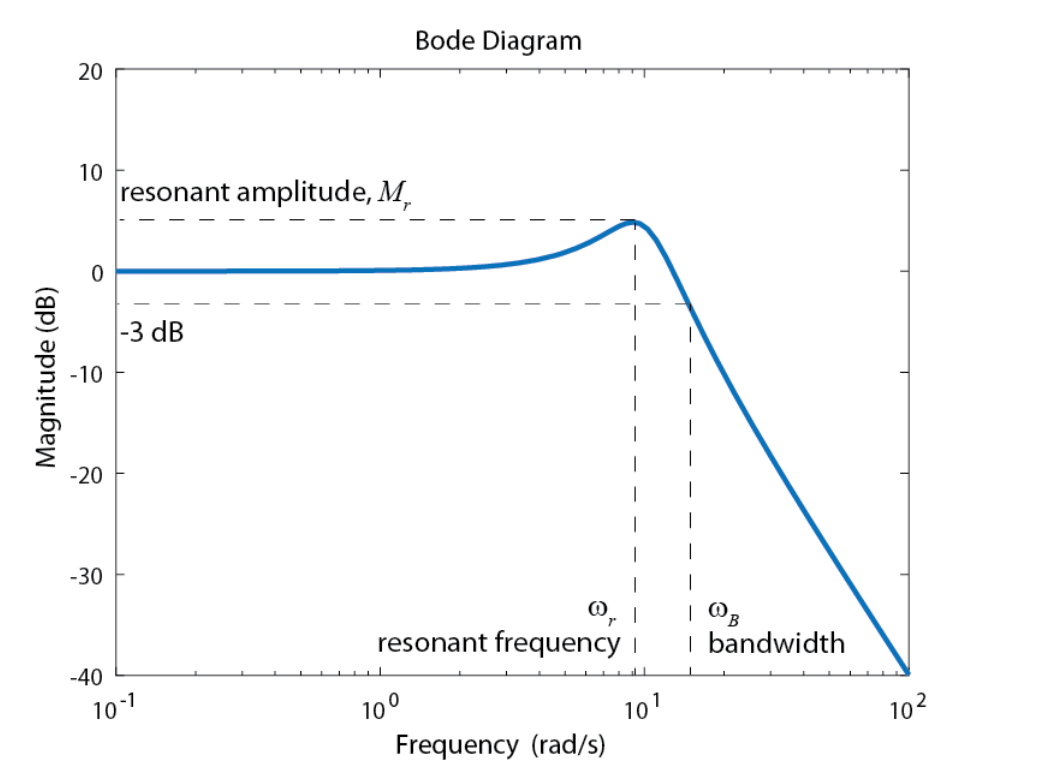

wn = 50;
zeta = 0.5;

omega = 0:0.01:2*wn; 
s = 1j*omega; 
MagResponse = 20*log10(abs(wn^2./(s.^2 + 2*zeta*wn*s+wn^2))); 

[Mr,ix] = max(MagResponse)

Mr = 1.2494

ix = 3537

wr = omega(ix)

wr = 35.3600


DistTo3DB = abs(MagResponse+3); 
[~,ix] = min(DistTo3DB); 
wb = omega(ix)

wb = 63.5600

## Problem 3

Open loop gain 


$$$ A = \frac{aK}{s-b} $ $$


Closed loop gain 


$$= \frac{A}{1+A} = \frac{aK}{s-b +aK}$$


The pole is located at 


$$s = b-aK$$


a = 1;
b = 10;
s = tf('s');
K = 1:20;
Kstable = []; i=1; 
Kunstable = []; j =1; 
Kmarginal = NaN;


for k = K
    p = b - a*k; 
    if p > 0
        Kunstable(i) = k; i = i +1; 
    elseif p < 0
        Kstable(j) = k; j = j+1; 
    else
        Kmarginal = k
    end

end

## Problem 4

Open loop gain 


$$A = \frac{K_i + sK_p}{s\left(Ts+s\right)}
$$


Closed loop gain 


$$\frac{A}{1+A} = \frac{K_i + sK_p}{Ts^2 + \left(1+K_p\right)s + K_i}$$


The poles of the system are the roots of 


$$s^2 +  \frac{1+K_p}{T}s + \frac{K_i}{T} = 0$$


Let the roots be 

$x = \alpha + j\beta$ and $y=\alpha - j\beta$ 

Then, 


$$x+y = 2\alpha = -\frac{1+K_p}{T} < -2a \\
\Rightarrow \frac{1+K_p}{T} > 2a \\
\Rightarrow K_p > 2aT-1$$


and 


$$xy = \alpha^2 + \beta^2 = \frac{K_i}{T} \\
\Rightarrow \beta^2 = \frac{K_i}{T} - \alpha^2 > b^2\\
\Rightarrow K_i > T \left(b^2 + \alpha^2)
$$


a = 5; 
b = 7;
T = 1;
epsilon = 0.1; 
Kp = 2*a*T-1 + epsilon; 
alpha = -(1+Kp)/(2*T); 
Ki = T*(b^2+alpha^2) + epsilon;